c) Diseñe un filtro paso alto con las siguientes características:  

• Tipo de respuesta: Highpass  

• Método de diseño: FIR – Constrained Equiripple  

• Orden del filtro: 100  

• Especificación de frecuencias:  

    o Fs: frecuencia de muestreo (a especificar por el alumno)  

    o Especificación: cutoff  

    o Fc: 𝑓𝑐𝐻

• Especificación de magnitudes: 

    o Astop = 80 dB  

    o Apass = 0,1 dB 

La frecuencia de corte (𝑓𝑐𝐻) ha de ser tal que atenúe en más de 80 dB la componente  continua y los dos armónicos fundamentales de menor frecuencia de x(t), y que altere lo  menos posible (menos de 3 dB) el resto de armónicos. Indique la frecuencia de corte (𝑓𝑐𝐻)  del filtro diseñado. 

Calcular la frecuencia de muestreo real (fs):

fs = 1 / (t(2) - t(1)); 
fprintf('Tu frecuencia de muestreo fs es: %.0f Hz\n', fs);

Tu frecuencia de muestreo fs es: 181000 Hz


Calcular el espectro (FFT):

L = length(x);
X = fft(x) / L;
X_mag = abs(fftshift(X));
f = linspace(-fs/2, fs/2, L);

Representar:

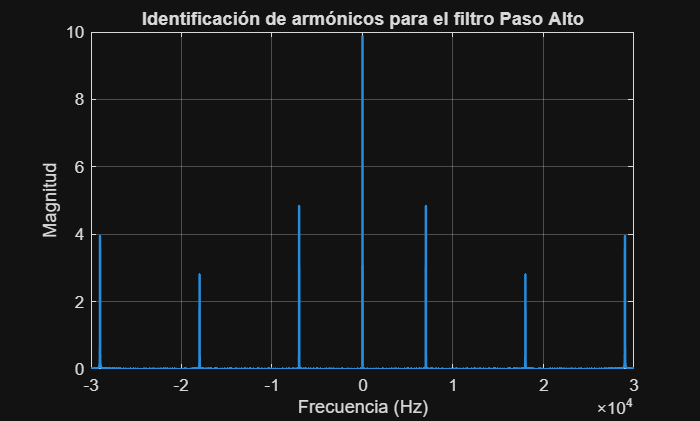

figure;
plot(f, X_mag, 'LineWidth', 1.5);
grid on;
xlim([-30000, 30000]); % Zoom en los primeros armónicos (0 a 30kHz)
xlabel('Frecuencia (Hz)');
ylabel('Magnitud');
title('Identificación de armónicos para el filtro Paso Alto');

Se utiliza: 

- Frecuencia stop: 20 000 Hz

- Frecuencia pass: 26 000 Hz

d) Justifique el correcto diseño del filtro mediante las gráficas que considere oportunas.

% 1. Filtrar la señal (suponiendo que exportaste los coeficientes como 'bk_alto')
% Si usaste la función filter:
g = filter(bk_alto, 1, x); 

Unrecognized function or variable 'bk_alto'.


% 2. Calcular espectro de la señal filtrada
G = fft(g) / length(g);
G_mag = abs(fftshift(G));
f = linspace(-fs/2, fs/2, length(g));

% 3. Gráfica de comparación
figure;
subplot(2,1,1);
plot(f, X_mag); % X_mag es el que calculamos antes para la original
title('Espectro Señal Original x[n]');
ylabel('Magnitud'); grid on; xlim([0 40000]);

subplot(2,1,2);
plot(f, G_mag, 'r');
title('Espectro Señal Filtrada g[n] (Paso Alto)');
xlabel('Frecuencia (Hz)'); ylabel('Magnitud'); grid on; xlim([0 40000]);

El diseño del filtro paso alto se considera correcto por los siguientes motivos:

- **Cumplimiento de la banda de parada:** Se ha establecido una frecuencia de corte de parada (Fstop*F**s**t**o**p*�) de **20.000 Hz**. Dado que los dos primeros armónicos fundamentales de la señal se encuentran en **7.200 Hz y 18.000 Hz**, ambos quedan dentro de la banda de parada. Como se observa en la respuesta en frecuencia del filtro, la atenuación en esta zona es superior a los **80 dB** requeridos, eliminando efectivamente la componente continua y dichos armónicos.

- **Preservación de la banda de paso:** La frecuencia de paso (Fpass*F**p**a**ss*�) se ha fijado en **26.000 Hz**. El tercer armónico (situado en **28.800 Hz**) y los sucesivos se encuentran en la banda de paso, donde la oscilación (ripple) es mínima (0.1 dB), cumpliendo con el objetivo de alterar lo menos posible el resto de la señal.

- **Resultado experimental:** En la comparativa de espectros se observa la desaparición total de los picos en 0, 7.200 y 18.000 Hz, mientras que el resto del espectro permanece inalterado.

SUPERPOSICIÓN

a) Empleando el filtro paso bajo diseñado en el bloque anterior, y empleando uno de los  métodos vistos en el primer bloque de la práctica, filtre la señal x(t) y obtendrá la  señal y[n].

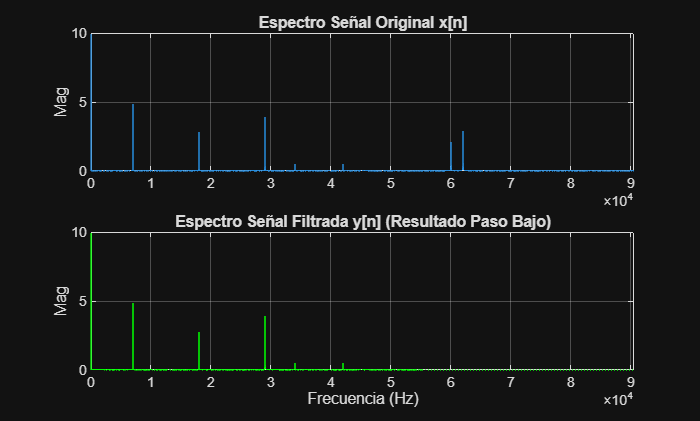

% Filtramos la señal original x
y = filter(LPF_COEF, 1, x); 

% Calculamos espectros para comparar
L = length(x);
f = linspace(-fs/2, fs/2, L);
X_mag = abs(fftshift(fft(x)/L));
Y_mag = abs(fftshift(fft(y)/L));

figure('Name', 'Apartado A: Filtrado Paso Bajo');
subplot(2,1,1);
plot(f, X_mag); title('Espectro Señal Original x[n]');
ylabel('Mag'); grid on; xlim([0 fs/2]);
subplot(2,1,2);
plot(f, Y_mag, 'g'); title('Espectro Señal Filtrada y[n] (Resultado Paso Bajo)');
xlabel('Frecuencia (Hz)'); ylabel('Mag'); grid on; xlim([0 fs/2]);

b) Empleando el filtro paso alto diseñado en el bloque anterior, filtre la señal y[n] y  obtendrá la señal g[n]. 

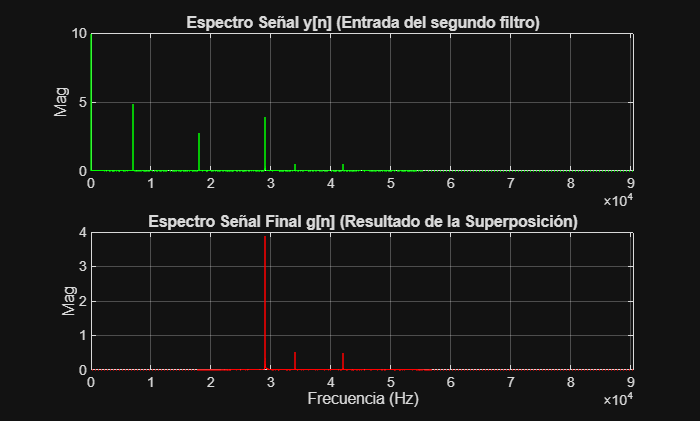

% Filtramos la señal 'y' (la que ya es paso bajo) con el filtro paso alto
g = filter(bk_alto, 1, y);

% Calculamos espectro del resultado final
G_mag = abs(fftshift(fft(g)/L));

figure('Name', 'Apartado B: Superposición (Paso Bajo + Paso Alto)');
subplot(2,1,1);
plot(f, Y_mag, 'g'); title('Espectro Señal y[n] (Entrada del segundo filtro)');
ylabel('Mag'); grid on; xlim([0 fs/2]);
subplot(2,1,2);
plot(f, G_mag, 'r'); title('Espectro Señal Final g[n] (Resultado de la Superposición)');
xlabel('Frecuencia (Hz)'); ylabel('Mag'); grid on; xlim([0 fs/2]);